## Determine the stress on the plate boundary in the Nankai trough

This is derived from the course project of Kaitlin Scheibe in 2022.

clc, clear
% Geographic coordinate system
e1_ned = [1;0;0]; % North
e2_ned = [0;1;0]; % East
e3_ned = [0;0;1]; % Down

E_ned = [e1_ned,e2_ned,e3_ned];

% Plotting coordinate system
e1_xyz = -e1_ned;
e2_xyz = e2_ned;
e3_xyz = -e3_ned;

E_xyz = [e1_xyz,e2_xyz,e3_xyz];

A = change_basis_tensor(E_xyz);


### Geological setting

The Nankai Trough Seismogenic Zone Experiment (NanTroSEIZE), a scientific drilling project conducted by the IODP, has spent over a decade drilling, sampling, imaging, and instrumenting the Nankai subduction zone, offshore Japan, with one of the primary goals of quantifying stress conditions along the plate boundary (Figure 1). The Nankai Trough is created by the subduction of the Philippine Sea plate beneath the Eurasian plate and is located southwest of the Kii Peninsula, Japan. Historically, the Nankai Trough has hosted magnitude 8.0 and greater seismic events and is one of the most tectonically active regions on Earth. 

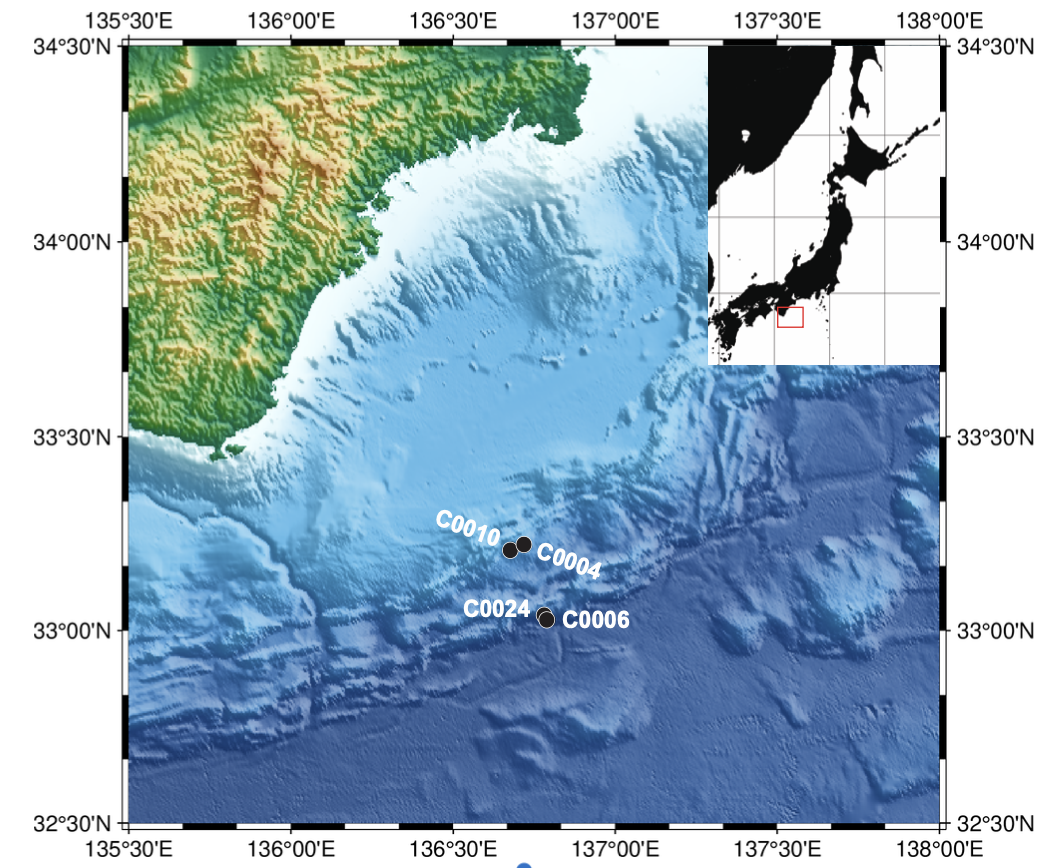     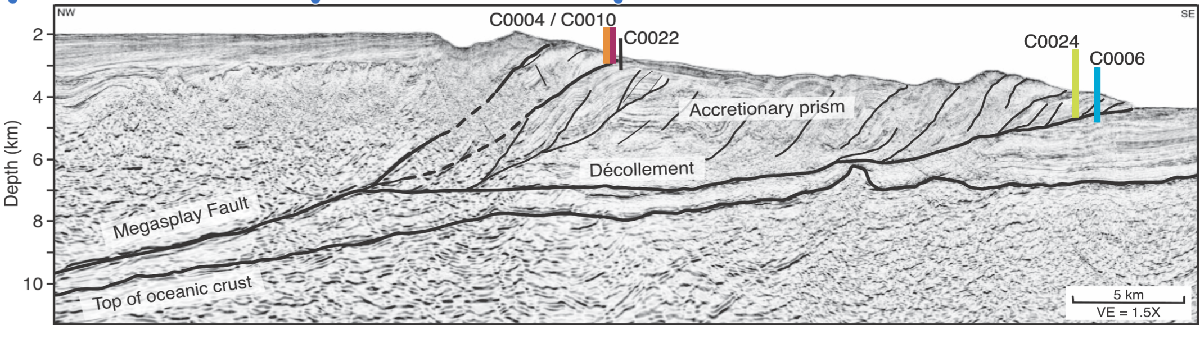

Figure 1:  top) Site map of the IODP NanTroSEIZE drilling sites, southeast Japan. bottom) Seismic cross section showing the Nankai subduction zone, accretionary wedge. Site C0004 is highlighted in orange, and the borehole crosses the Megasplay thrust fault. 

### Geometry of the thrust fault

In 2004, the Integrated Ocean Drilling Program (IODP) drilled Site C0004 with the primary objective of accessing the shallow portion of a major thrust fault in the accretionary wedge, termed the megasplay fault. At site C0004 the megasplay fault is crossed at 300 meters below sea floor (mbsf). The megasplay fault strikes 60°-240° and dips 20° to the NW (Moore et al., 2009). 

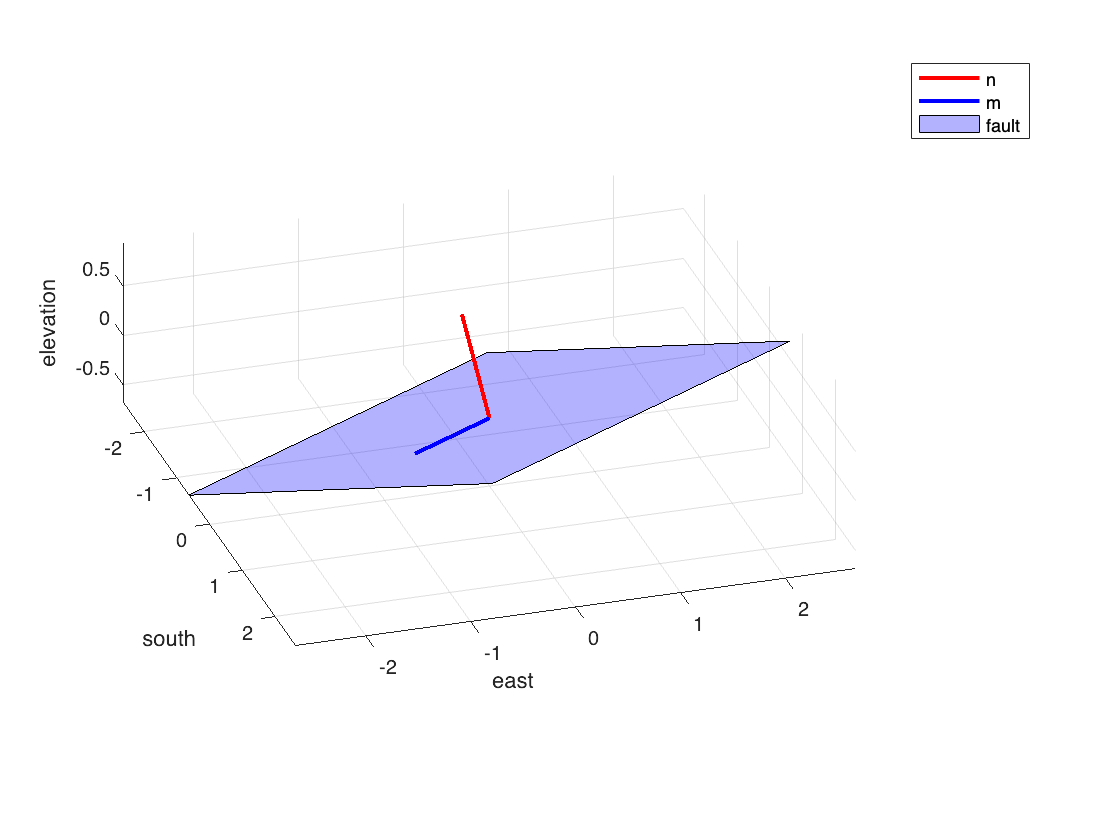

% North-East-Down base vectors
dip_rad = deg2rad(20);
strike_rad = deg2rad(240); 
Q = @(r,theta) r*r' + cos(theta)*(eye(3) - r*r') + sin(theta) *[0 -r(3) r(2);r(3) 0 -r(1);-r(2) r(1) 0];
QD = Q(e1_ned,dip_rad); % should this have a minus sign?!?
QS = Q(e3_ned,strike_rad);

% Strike
m_ned = QS*e1_ned;
% m_xyz = A*m_ned;

% Normal to fault plane
n_ned = QS*QD*(-e3_ned);
% n_xyz = A*n_ned

[fault] = plot_fault(n_ned,m_ned,E_xyz);
view([72.65 26.13])

### Determining the local stress field

#### Stress mangnitudes

At the time of drilling, resistivity at the bit (RAB) images were collected, which give a visual image of what the borehole looks like while being cored (Figure 2). RAB images provide information about wellbore failures (breakouts and tensile fractures). The width of a breakout can be used to calculate a range of horizontal far field stresses that result in the tensile failure of the wellbore wall. 

Far field horizontal stresses are calculated from the borehole breakout widths at 300 mbsf. The azimuth of the breakouts is 50° and 230°. The magnitude of horizontal stresses are: 

- minimum horizontal stress: Shmin = 5 MPa

- maximum horizontal stress: SHmax = 9.5 MPa 

Assuming a bulk density of 1360 kg/m^3 for the overlying sediments and gravitational acceleration of 9.81 m/s^2 the vertical stress is

Sv = 1360*9.81*300/1e6 % [MPa]

Sv = 4.0025

The principal stresses are therefore:

sig1 = 9.5; % [MPa] SHmax
sig2 = 5;   % [MPa] Shmin
sig3 = Sv;  % [MPa] Sv

sig_pri = [sig1 0 0;...
           0 sig2 0;...
           0  0 sig3];

#### Stress directions

We know that the vertical stress is, well vertical and we know the direction if the minimum horizontal stress from the breakouts. These are the third and second principal directions respectively. We can obtain the firs principal direction from the cross product.

% Second principal direction
strike_Shmin = deg2rad(230); 
QS_Shmin = Q(e3_ned,strike_Shmin);
v2_ned = QS_Shmin*e1_ned;

% Third principal direction
v3_ned = e3_ned;

% First principal direction
v1_ned = cross(v2_ned,v3_ned);

cross(v1_ned,v2_ned)'*v3_ned;

E_sig = [v1_ned,v2_ned,v3_ned]

E_sig =    -0.7660   -0.6428         0
    0.6428   -0.7660         0
         0         0    1.0000



% Stress tensor in geographic reference frame
A = change_basis_tensor(E_sig)

A =    -0.7660   -0.6428         0
    0.6428   -0.7660         0
         0         0    1.0000



sig_ned = A*sig_pri*A'

sig_ned =     7.6407   -2.2158         0
   -2.2158    6.8593         0
         0         0    4.0025


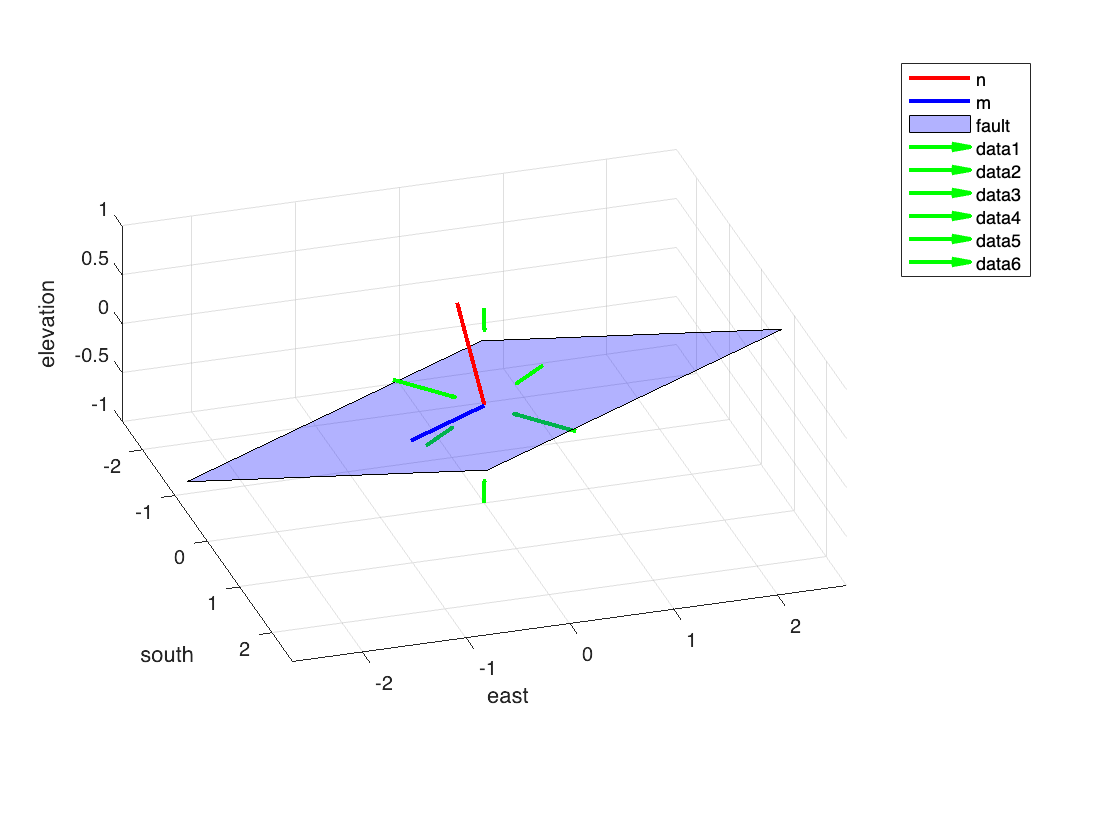


plot_stress_orientation(E_sig,E_xyz)

### Find traction of the fault

Once the stress tensor and the normal are known, we ontaine the traction and the normal and shear stress on the fault

tn = sig_ned*n_ned

tn =     2.6421
   -1.8293
   -3.7611


% parallel and perpendicular components via projection matrices
tn_par = (n_ned*n_ned')*tn

tn_par =     1.3713
   -0.7917
   -4.3505


tn_per = (eye(3)-n_ned*n_ned')*tn

tn_per =     1.2708
   -1.0376
    0.5894


sig_n = n_ned'*tn

sig_n = 4.6297

tau   = m_ned'*tn

tau = 0.2632

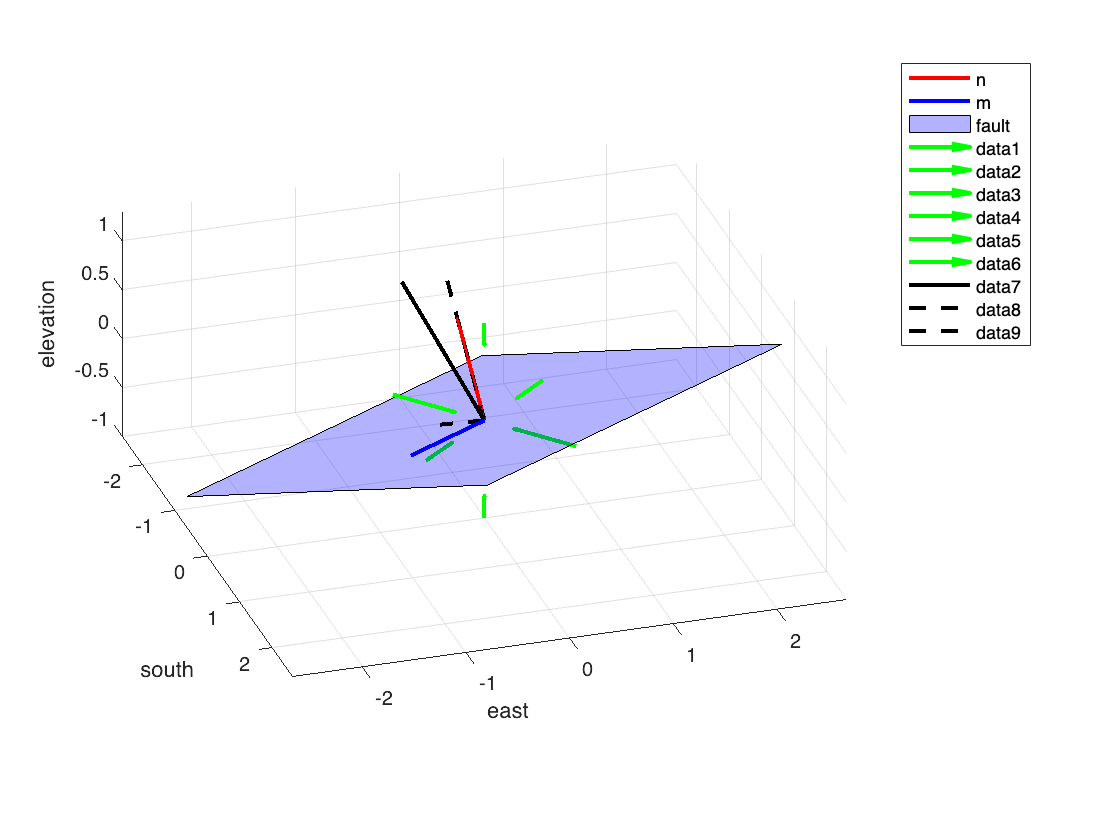

plot_traction(tn,tn_par,tn_per,E_xyz)

### Change of basis tensor

function [A] = change_basis_tensor(Ep)
% author: Marc Hesse
% date: Sep 25, 2023
% Description: Computes the "change of basis" tensor A between two reference frames {e} and {e'},
% so that vectors transform as:
%              [v] = [A][v]' 
%              [v]'= [A]^T[v]
% and tensors transform as
%              [S] = [A][S][A]^T
%              [S]'= [A]^T[S][A]
%
% Input:
% Ep = [[ep1], [ep2], [ep3]] matrix containing the primed basis vectors 
%                        in the UNprimed frame
% Output: 
% A = change of basis matrix
E = eye(3);
e1 = E(:,1); e2 = E(:,2); e3 = E(:,3);

ep1 = Ep(:,1); ep2 = Ep(:,2); ep3 = Ep(:,3);

A = [e1'*ep1 e1'*ep2 e1'*ep3;...
     e2'*ep1 e2'*ep2 e2'*ep3;...
     e3'*ep1 e3'*ep2 e3'*ep3];
end					

### Plot fault plane normal and strike				

function [fault] = plot_fault(n,m,E_xyz)

% Input:
% n = fault normal (unit)
% m = strike vector (unit)


A = change_basis_tensor(E_xyz);

n_xyz = A*n; m_xyz = A*m;

% Dip vector
d_xyz = cross(n_xyz,m_xyz);

% Corners of fault outline
corner1 = 2*(d_xyz+m_xyz);
corner2 = 2*(d_xyz-m_xyz);
corner3 =  2*(-d_xyz-m_xyz);
corner4 =  2*(-d_xyz+m_xyz);

% Outline of fault plane
fault.x = [corner1(1);corner2(1);corner3(1);corner4(1);corner1(1)];
fault.y = [corner1(2);corner2(2);corner3(2);corner4(2);corner1(2)];
fault.z = [corner1(3);corner2(3);corner3(3);corner4(3);corner1(3)];

% Plotting
plot3([0 n_xyz(1)],[0 n_xyz(2)],[0 n_xyz(3)],'r','linewidth',2), hold on
plot3([0 m_xyz(1)],[0 m_xyz(2)],[0 m_xyz(3)],'b','linewidth',2)
patch(fault.x,fault.y,fault.z,'b'), alpha(0.3)
grid on
xlabel 'south',
ylabel 'east'
zlabel 'elevation'
legend('n','m','fault')
axis equal

end

### Plot stress orientation

function [] = plot_stress_orientation(E_sig,E_xyz)
% Change basis to XYZ
A = change_basis_tensor(E_xyz);
e1 = A*E_sig(:,1); e2 = A*E_sig(:,2); e3 = A*E_sig(:,3);

s1 = .75;
s2 = .5;
s3 = .25;
quiver3(e1(1),e1(2),e1(3),-s1*e1(1),-s1*e1(2),-s1*e1(3),'linewidth',2,'color','g');
quiver3(-e1(1),-e1(2),-e1(3),s1*e1(1),s1*e1(2),s1*e1(3),'linewidth',2,'color','g')

quiver3(e2(1),e2(2),e1(3),-s2*e2(1),-s2*e2(2),-s2*e2(3),'linewidth',2,'color','g');
quiver3(-e2(1),-e2(2),-e2(3),s2*e2(1),s2*e2(2),s2*e2(3),'linewidth',2,'color','g');

quiver3(e3(1),e3(2),e3(3),-s3*e3(1),-s3*e3(2),-s3*e3(3),'linewidth',2,'color','g');
quiver3(-e3(1),-e3(2),-e3(3),s3*e3(1),s3*e3(2),s3*e3(3),'linewidth',2,'color','g')


end

### Plot the traction and its components

function [] = plot_traction(tn,tn_par,tn_per,E_xyz)
% Change basis to XYZ
A = change_basis_tensor(E_xyz);
tn     = A*tn;
tn_par = A*tn_par;
tn_per = A*tn_per;
scale = .3;
plot3(scale*[0 tn(1)],scale*[0 tn(2)],scale*[0 tn(3)],'k','linewidth',2)
plot3(scale*[0 tn_par(1)],scale*[0 tn_par(2)],scale*[0 tn_par(3)],'k--','linewidth',2)
plot3(scale*[0 tn_per(1)],scale*[0 tn_per(2)],scale*[0 tn_per(3)],'k--','linewidth',2)
end